# INTERPOLACJA

## Zespolona transformata Fouriera

Na początek przećwiczymy sobie to czym jest zespolona transformata Fouriera, jak jest liczona i jak ma się do transformaty rzeczywistej.

**ĆWICZENIE 1**

To ćwiczenie ma na celu pokazanie, że transformata DFT jest rodzajem interpolacji. Zobaczymy też podstawowe właściwości transformaty DFT.

% Pierwszym elementem niezbędnym do przeprowadzenia obliczeń jest wektor
% danych wejściowych. MUSI TO BYĆ WEKTOR PRÓBEK ROZŁOZONYCH RÓWNOMIERNIE!
% W przypadku cyfrowego przetwarzania sygnałów, do którego DFT jest
% wykorzystywane, generacja tego wektora ma odzwierciedlać rzeczywisty
% system. Dlatego nie będziemy tego robili np. tak:


tmin=0;
tmax=2.0;


x_tak_nie_robimy = linspace(tmin,tmax,301); %301 próbek od 0 - 2 s

% Będziemy patrzyli na temat z poziomu systemu pomiarowego, czyli zrobimy
% to samo tak:

N = 301;            % Długość rekordu danych w ilości próbek

h = (tmax-tmin)/N;        % długość kroku w [s] 
f_s = 1/h;          % częstotliwość próbkowania (normalnie jej nie wyliczamy, 
                    % ale po prostu jest to jedna z metadanych pochodzących
                    % z systemu akwizycji danych
                    
T = N*1./f_s;       % długość rekordu danych w skali czasu

t = tmin + (0:N-1)/f_s;    % wektor x-owych współrzędnych próbek (dokładnie N próbek)

 

Jak wiemy sama transformata DFT działa na próbkach (indeksowana jest względem n). Wygenerujmy teraz i zanalizujmy przykładowy wynik transformaty DFT:

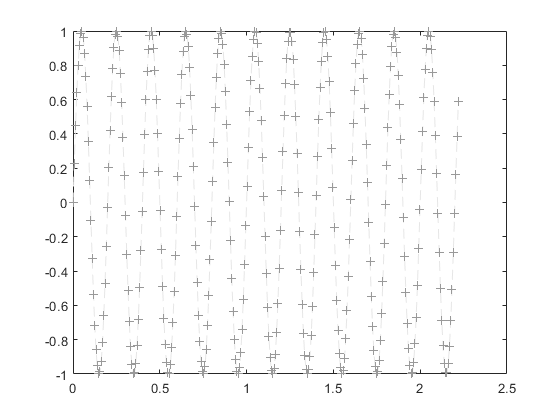

% analizować będziemy najprostszy sygnał - sinusoidalny. Patrząc z punktu
% widzenia interpolacji powinniśmy otrzymać pojedynczy współczynnik (dla
% transformaty rzeczywistej)

f=5;                           %częstotliwość sygnału w Hz
func = @(t)sin(2*pi.*f.*t);    % oryginalny sygnał
y = func(t);                   % wektor wartość y-kowych próbek

tt = linspace(tmin,tmax,1001);       % wektor do rysowania

% Wyrysujemy sytuację z danymi wejściowymi
plot(tt,func(tt),'k--','Color',[0.9,0.9,0.9]); hold on;
plot(t,y,'+','Color', [0.6,0.6,0.6]); hold off;

Obliczymy teraz Zespoloną DFT dla tego sygnału:

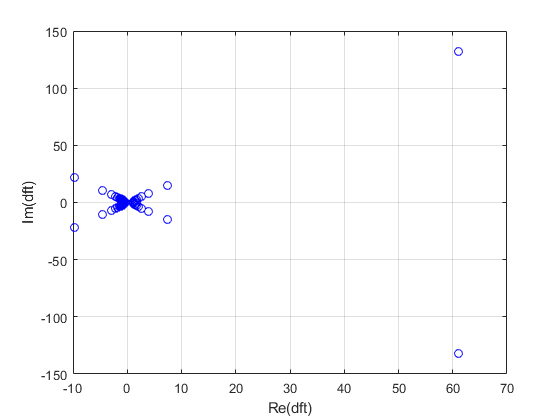

% Wykorzystamy algorytm FFT
% Zwróć uwagę, że do algorytmu podajemy tylko wektor y-ków. To dlatego, że
% DFT działa zawsze na indeksach próbek, zatem położenia w skali
% niezależnej są dla tego algorytmu nieistotne

dft = fft(y);

% Wyrysujmy sobie położenie współczynników transformaty (interpolacji) na
% płaszczyźnie zespolonej

compl_pl = plot(real(dft),imag(dft),'ob'); xlabel('Re(dft)'); ylabel('Im(dft)');grid on;

Ten wykres może wyglądać dziwnie na pierwszy rzut oka, ale zwróćmy uwagę, że wszystkie współczynniki zespolone są prawie równe 0 **poza dwoma symetrycznie rozłożonymi współczynnikami względem zera**.

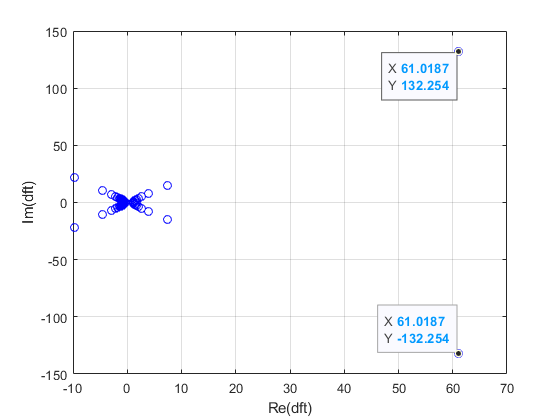

oustandingInd = find(abs(dft)>10);
y_tip = imag(dft(oustandingInd));
x_tip = real(dft(oustandingInd));
dt1 = datatip(compl_pl,x_tip(1),y_tip(1));
dt2 = datatip(compl_pl,x_tip(2),y_tip(2));

fprintf('Indeks najwyższej składowej to %d\n', oustandingInd)

Indeks najwyższej składowej to 12
Indeks najwyższej składowej to 292


Bardziej czytelny dla niewprawionej osoby jest wykres amplitudowy. Z numerycznego punktu widzenia do policzenia DFT wymagane było 

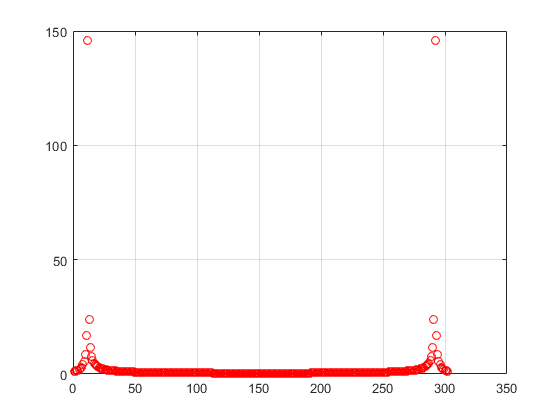

ampl = abs(dft);
plot(ampl, 'or');grid on;

fprintf('Indeks najwyższej składowej to %d\n', oustandingInd);

Indeks najwyższej składowej to 12
Indeks najwyższej składowej to 292


Wykres ten jest pokazany względem indeksu próbki - w taki sposób często przedstawiany jest w przetwarzaniu sygnałów. Jednak my wiemy, że stworzenie nowej bazy funkcji dla transformaty DFT wymagało wykonania pewnego zabiegu na sposobie indeksacji punktów, które zamiast z przedziału $\left\lbrack 0,2\pi \right\rbrack$ zmienił się na ze względu na  $\left\lbrack -\pi ,\pi \right\rbrack$ zależności matematyczne między postacią zespoloną liczy Eulera, a funkcjami sin(x) i cos(x). Przykładowo:


$$\cos \left(x\right)=\frac{e^{\textrm{ix}} +e^{-\textrm{ix}} }{2}$$



$$\sin \left(x\right)=\frac{e^{\textrm{ix}} -e^{-\textrm{ix}} }{2}$$


ponieważ nasza baza interpolacyjna jest w postaci $e^{\textrm{ix}}$  część z tych indeksów powinna mieć wartość ujemną. Jeżeli przeanalizuje się powyższe zależności matematyczne to okazuje się, ze druga połowa transformaty (z przedziału $\left\lbrack \pi ,2\pi \right\rbrack$) powinna zostać przesunięta względem zera (do przedziału $\left\lbrack -\pi ,0\right\rbrack$), ponieważ jak widzimy istnieje tam sygnał w przetwarzaniu sygnałów często mówi się o częstotliwościach ujemnych w DFT.

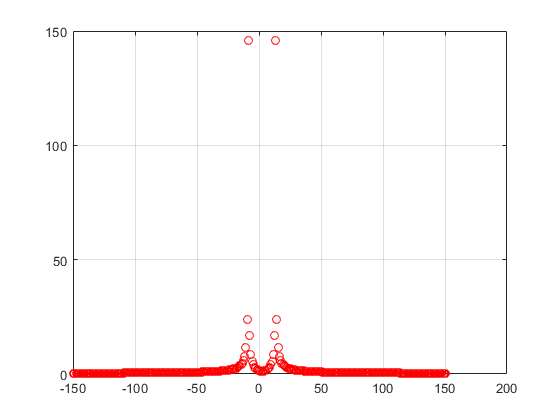

ampl = abs(dft);
ampl_shifted = [ampl(ceil(N/2):end), ampl(1:floor(N/2)-1)];
index = [1:1:N]-(N/2);
plot(index, ampl_shifted, 'or');grid on;

fprintf('Indeks najwyższej składowej to %d\n', oustandingInd);

Indeks najwyższej składowej to 12
Indeks najwyższej składowej to 292


Dwa odstające punkty są to zespolone współczynniki obliczone w procesie interpolacji stojące przy funkcjach  $e^{\textrm{ix}}$ oraz $e^{-\textrm{ix}}$ tworzących naszą bazę funkcji interpolujących dające razem odwzorowanie naszej funkcji i $\sin \left(x\right)$ zgodnie ze wzorem:


$$\sin \left(x\right)=\frac{e^{\textrm{ix}} -e^{-\textrm{ix}} }{2}$$


W tym sensie zespolona transformata DFT różni się od transformaty rzeczywistej.

**UWAGA! **W przypadku przetwarzania sygnałów często widma amplitudowe i fazowe są pokazywane tylko z połowie. Wynika to z faktu, że są to widma zawsze symetryczne zgodnie z opisaną powyżej zasadą. Różne biblioteki w różny sposób zwracają wynik transformaty DFT.

Na koniec dla kompletności przypiszemy kolejnym indeksom wartości w dziedzinie częstotliwości. Zgodnie z opisaną teorią odległość między punktami transformaty w dziedzinie częstotliwości zależy od odległości między próbkami (ilością n-tych pierwiastków jedynki), a więc od częstotliwości próbkowania. Wiemy że liczba współczynników otrzymanych z transformaty DFT jest dwa razy większa niż największa częstotliwość (bo dla każdej składowej DFT mamy dwa współczynniki), zatem:

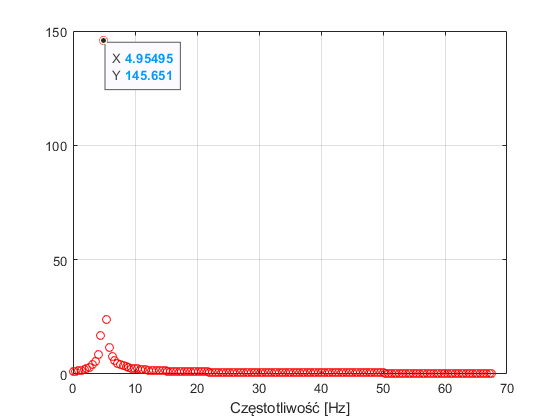

ampl = abs(dft);
ampl_real = ampl(1:fix(N/2)+1);
frequency = [0:f_s/N:f_s/2];
am_pl = plot(frequency, ampl_real, 'or');grid on;
xlabel('Częstotliwość [Hz]');
oustandingInd = find(ampl_real>50);
y_tip = ampl_real(oustandingInd);
x_tip = frequency(oustandingInd);
dt1 = datatip(am_pl,x_tip(1),y_tip(1));

Zwróć uwagę na wartość częstotliwości jaka jest wyświetlana. Będzie to ważne w następnym ćwiczeniu.

**ĆWICZENIE 2:**

W tym ćwiczeniu zobaczymy czym są współczynniki transformaty DFT. Do jego realizacji jest konieczne wykonanie kodu z Ćwiczenia 1. 

W ćwiczeniu 1 zobaczyliśmy już, że DFT można policzyć w dwóch postaciach - koncepcyjnie prostszej rzeczywistej DFT i bardziej złożonej, ale znacznie wydajniejszej obliczeniowo zespolonej DFT. Czym zatem są współczynniki transformaty DFT?

Pokażemy to na przykładzie zespolonej transformaty ze względu na fakt, że jedyne wydajne algorytmy obliczania DFT (algorytmy FFT) działają tylko na transformacie zespolonej. Problemy z obliczeniem rzeczywistej DFT na komputerze mogłeś obserwować na poprzednim ćwiczeniu. 

Tematem zajęć jest wykorzystanie interpolacji do obliczania współczynników korelacji. Zobaczmy zatem jaką korelacją są współczynniki uzyskane w ramach DFT:

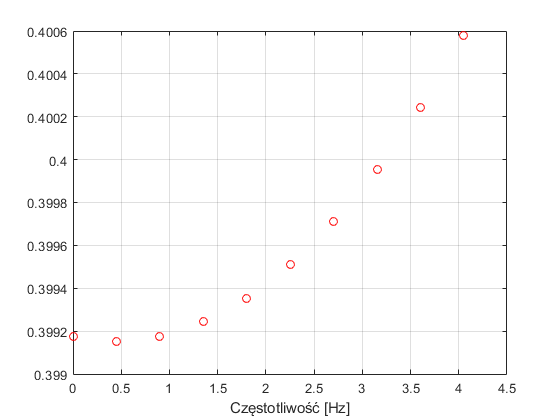

% Wykonaj kody z Ćwiczenia 1 jeżeli jeszcze tego nie zrobiłeś

% Poniżej wyświetlony zostanie początkowy fragment widma amplitudowego
% pokazanego w Ćwiczeniu 1

ampl = abs(dft);
ampl_real = ampl(1:fix(N/2)+1);
frequency = [0:f_s/N:f_s/2];
am_pl = plot(frequency(1:10), ampl_shifted(1:10), 'or');grid on;
xlabel('Częstotliwość [Hz]');


% ... i zostaną wyświetlnoe kluczowe informacje 
fprintf('Okres próbkowania (okno) to T=%f [s]\n', T);

Okres próbkowania (okno) to T=2.220000 [s]


fprintf('Częstotliwość odpowiadająca oknu to F=%f [Hz]\n', 1/T);

Częstotliwość odpowiadajaca oknuto  to F=0.450450 [Hz]


Zwróć uwagę na pierwsze dwie próbki widma transformaty (abstrahujemy na razie od tego że jest to transformata zespolona). Pierwsza próbkę odpowiada częstotliwości  $f=0\;\textrm{Hz}$ czyli składowej stałej. Druga próbka odpowiada natomiast częstotliwości $f=0\ldotp 5\;\textrm{Hz}$,  czyli podstawowej częstotliwości odpowiadającej długości okna próbkowania. Oznacza to że pierwszy współczynnik jaki dostajemy w przypadku transformaty rzeczywistej odpowiada współczynnikowi korelacji sygnału oryginalnego z sygnałem sinusoidalnym bądź cosinusoidalnym o częstotliwości odpowiadającej długości okna obserwacji zgodnie z bazą funkcji interpolacyjnych właściwych dla tej interpolacji:


$$\begin{array}{l}
b_0 =0\\
b_k =\sin \left(\frac{2\pi k}{N}x\right),\;b_{k+1} =\cos \left(\frac{2\pi k}{N}x\right)
\end{array}$$


ta sama informacja jest zawarta w zespolonej transformacie Fouriera, ale wzorcowa funkcja sin(x) lub cos(x) jest przetworzona do postaci bazy zespolonej zgodnie z poznaną przez nas formułą:


$$\sin \left(x\right)=\frac{e^{\mathrm{ix}} -e^{-\mathrm{ix}} }{2i}$$


Kluczowa jest jednak informacja, że DFT w istocie liczy współczynniki korelacji pomiędzy sygnałem a kolejnymi harmonicznymi wzorcowego sygnału o okresie równym długości przedziału próbkowania (okna).

W Ćwiczeniu 1 miałeś pokazany bardzo szczególny przypadek - w którym okres okna próbkowania jest wielokrotnością okresu sygnału. To najprostszy przypadek bo jeżeli tak jest to w dowolnej transformacie Fouriera kolejne funkcje z bazy są porostu kolejnymi harmonicznymi okresu podstawowego i któraś z nich "wstrzela" się praktycznie idealnie w częstotliwość. Przykładowo w Ćwiczeniu 1:


$$f_{\textrm{sygnału}} =5\;\textrm{Hz}$$



$$f_{\textrm{okna}} =0\ldotp 5\;\textrm{Hz}$$


w przypadku transformaty rzeczywistej kolejne funkcje z bazy interpolacyjnej wyglądałyby następująco:


$$\begin{array}{l}
b_0 =0\\
b_1 =\sin \left(\frac{2\pi 1}{301}x\right),\;b_2 =\cos \left(\frac{2\pi 1}{301}x\right),\\
b_3 =\sin \left(\frac{2\pi 2}{301}x\right),\;b_4 =\cos \left(\frac{2\pi 2}{301}x\right),\\
\ldotp \ldotp \ldotp 
\end{array}$$


przyjrzyjmy się np. funkcji $b_1$. Czynnik $\frac{2\pi 1}{301}$oznacza, ze jest to sinus o podstawowej pulsacji równanej  $2\pi$na całym przedziale 301 zebranych próbek.

Kolejna funkcja np.  będzie sinusem o dwukrotnie większej częstotliwości. Aż w końcu dla funkcji  jest to sinus o częstotliwości  $f=10*0\ldotp 5\textrm{Hz}=5\textrm{Hz}$, która odpowiada dokładnie częstotliwości naszego sygnału. W związku z tym współczynnik korelacji jest maksymalny, a pozostałe współczynniki la innych częstotliwości są równe lub prawie równe 0. 

Sytuacja zmieni się, jeżeli okres próbkowania nie bezie wielokrotnością okresu sygnału. Żeby zobaczyć jak się zmieni ustaw długość okna w Ćwiczeniu pierwszym np. na wartość T=2.22 s. Zaobserwuj jak wpłynie to na wynik obliczeń transformaty. Czy potrafisz zinterpretować ten efekt?

W przetwarzaniu sygnałów nazywany jest on efektem okna. 